# Hopf Model

## Single region

### Without noise

In the case without noise, the dynamic behavior of single region is described by the following differential equation


$$\dot{z} =\left(\alpha +i\omega -{\left|z\right|}^2 \right)z$$


where $\alpha$ is a bifurcation parameter and $\omega$is an angular velocity. The variable $z$ is a compleZ number; i.e $z=x+\mathrm{iy}$. This can be used to separate the real ($x$) and imaginary ($y$) parts and get two differential equations:


$$\begin{array}{l}
\dot{z} =\left(a+i\omega -{\left|x+\mathrm{iy}\right|}^2 \right)\cdot \left(x+\mathrm{iy}\right)\\
\;\;=\left(a+i\omega -{\sqrt{x^2 +y^2 }}^2 \right)\cdot \left(x+\mathrm{iy}\right)\\
\;\;=\left(a+i\omega -\left(x^2 +y^2 \right)\right)\cdot \left(x+\mathrm{iy}\right)\\
\;\;=\left(a+i\omega -x^2 -y^2 \right)\cdot \left(x+\mathrm{iy}\right)\\
\;\;=\left(\alpha +i\omega -x^2 -y^2 \right)\cdot x+\left(\alpha +i\omega -x^2 -y^2 \right)\cdot \mathrm{iy}\\
\;\;=\alpha x+i\omega x-\mathrm{x³}-\mathrm{y²x}+\alpha \mathrm{iy}-\omega y-\mathrm{x²iy}-{\mathrm{iy}}^3 
\end{array}$$


Now we collect all real parts (everything without $i$) and all imaginary parts (everything with $i$) in separate differential equations:


$$\begin{array}{l}
\dot{x} =\alpha x-\textrm{x³}-\textrm{y²x}-\omega y\\
\dot{y} =\omega x+\alpha y-\mathrm{x²y}-y^3 
\end{array}$$


and we re-arrange and factor out $x$ and $y$ to get


$$\begin{array}{l}
\dot{x} =\left(\alpha -{\textrm{x}}^2 -\textrm{y²}\right)x-\omega y\\
\dot{y} =\left(\alpha -\textrm{x²}-{\textrm{y}}^2 \right)y+\omega x
\end{array}$$


#### Implementation

For this implementation we use the ode45 solver.

f_hopf = @(Z,alpha,omega)...      % ODEs for Z and y
    [(alpha - Z(1).^2 -Z(2).^2) .* Z(1) - omega * Z(2);...
    (alpha - Z(1).^2 -Z(2).^2) .* Z(2) + omega * Z(1)];

t_start = 0;                      % simulation start time (seconds)
t_end = 100;                      % simulation end time (seconds)
dt = 1e-2;                        % time step (seconds)

t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);

freq = 0.1;                       % intrinsic frequency (Hz)
omega = 2 * pi * freq;            % angular velocity
alphas = [-.1,0,.1];
Z_0 = [.05,.05];                  % initial conditions

fprintf('Hopf model - single region - without noise')

Hopf model - single region - without noise

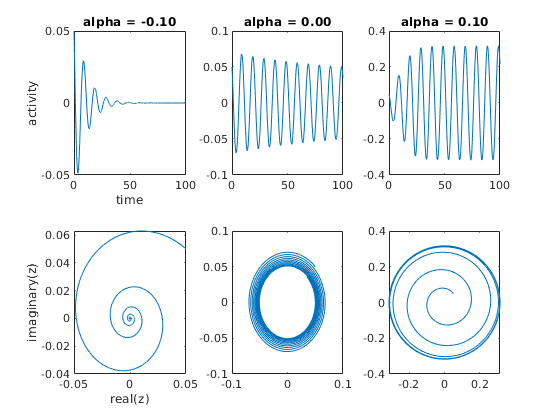

figure
for i=1:3
    [~,Z]     = ode45(@(t,Z)f_hopf(Z,alphas(i),omega),T,Z_0);
    subplot(2,3,i)
    plot(T,Z(:,1))
    title(sprintf('alpha = %.2f', alphas(i)))
    subplot(2,3,i+3)
    plot(Z(:,1),Z(:,2))
end
subplot(2,3,1)
xlabel('time')
ylabel('activity')
subplot(2,3,4)
xlabel('real(z)')
ylabel('imaginary(z)')

### With noise

The brain is noisy and the noise is computationally meaningful. Therefore, we want to add a noise term to our Hopf region model in the form of a Wiener process:


$$\sigma \Delta w=\sqrt{\Delta t}N\left(0,1\right)\;$$


t_start = 0;                      % simulation start time (seconds)
t_end = 100;                      % simulation end time (seconds)
dt = 1e-2;                        % time step (seconds)
t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);

sigma = 0.02;
dsig = sigma * sqrt(dt);
w = randn(1,t_steps);
for t=2:t_steps
    w(t) = w(t-1) + dsig * w(t);
end

fprintf('Wiener process')

Wiener process

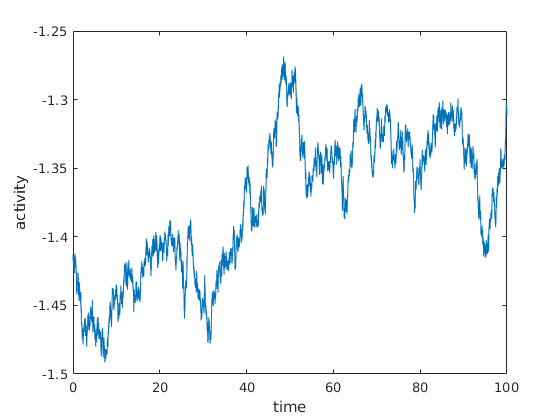

figure
plot(T,w)
xlabel('time')
ylabel('activity')

With this the Hopf model becomes


$$\begin{array}{l}
\Delta x=\left\lbrack \left(\alpha -{\mathrm{x}}^2 -\textrm{y²}\right)x-\omega y\right\rbrack \Delta t+\sigma \Delta w\\
\Delta y=\left\lbrack \left(\alpha -\textrm{x²}-{\mathrm{y}}^2 \right)y+\omega x\right\rbrack \Delta t+\sigma \Delta w
\end{array}$$


#### Implementation

For this implementation we can no longer use the ode45 solver because we have a random (stochastic) element in our differential equation. We will use the [Euler-Maruyama method](https://en.wikipedia.org/wiki/Euler%E2%80%93Maruyama_method), which we implement ourselves.

f_hopf = @(Z,alpha,omega)...      % ODEs for Z and y
    [(alpha - Z(1).^2 -Z(2).^2) .* Z(1) - omega * Z(2),...
    (alpha - Z(1).^2 -Z(2).^2) .* Z(2) + omega * Z(1)];

t_start = 0;                      % simulation start time (seconds)
t_end = 100;                      % simulation end time (seconds)
dt = 1e-2;                        % time step (seconds)

t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);

freq = 0.1;                       % intrinsic frequency (Hz)
omega = 2 * pi * freq;            % angular velocity
alphas = [-.1,0,.1];
Z_0 = [.05,.05];                  % initial conditions
Z = ones(t_steps,2) .* Z_0;

sigma = 0.02;
dsig = sigma * sqrt(dt);


fprintf('Hopf model - single region - with noise')

Hopf model - single region - with noise

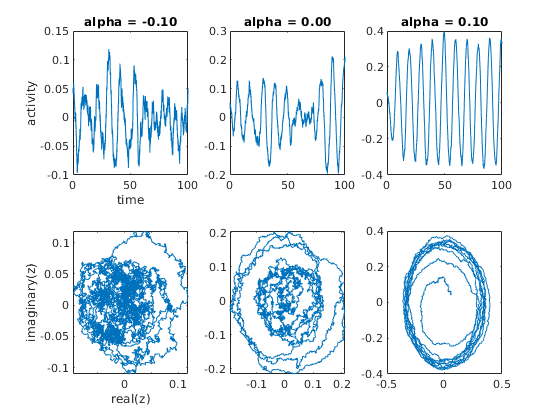

figure
for i=1:3
    for t=2:t_steps
        Z(t,:) = Z(t-1,:) + dt * f_hopf(Z(t-1,:),alphas(i),omega) + ...
            dsig * randn(1,2);
    end
    
    subplot(2,3,i)
    plot(T,Z(:,1))
    title(sprintf('alpha = %.2f', alphas(i)))
    subplot(2,3,i+3)
    plot(Z(:,1),Z(:,2))
end
subplot(2,3,1)
xlabel('time')
ylabel('activity')
subplot(2,3,4)
xlabel('real(z)')
ylabel('imaginary(z)')

## Multiple regions

In order to accommodate multiple regions, the Hopf model needs to be eZtended to allow interactions between brain regions:


$$\begin{array}{l}
\Delta x_j =\left\lbrack \left(\alpha -{\mathrm{x}}^2 -\textrm{y²}\right)x-\omega y+G\sum_i C_{\mathrm{ij}} \left(x_i -x_j \right)\right\rbrack \Delta t+\sigma \Delta w\\
\Delta y_j =\left\lbrack \left(\alpha -\textrm{x²}-{\mathrm{y}}^2 \right)y+\omega x+G\sum_i C_{\mathrm{ij}} \left(y_i -y_j \right)\right\rbrack \Delta t+\sigma \Delta w
\end{array}$$


This new term allows pairs of brain regions $j$ and $i$ to synchronize as they try to adjust their activity to each other. The eZtent to which this tendency to synchronize is eZpressed depends on the strength of the connection between the two regions $\left(C_{\mathrm{ij}} \right)$scaled by a global factor $G$.

### Region pairs

C = [0,1;1,0];
Gs = linspace(0.01,0.1,4);

t_start = 0;                      % simulation start time (seconds)
t_end = 100;                      % simulation end time (seconds)
dt = 1e-2;                        % time step (seconds)

t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);

freq = [0.045;0.06];              % intrinsic frequencies (Hz)
omega = 2 * pi * freq;            % angular velocities
alpha = 0.25;
X = randn(2,t_steps) .* 1e-2;
Y = randn(2,t_steps) .* 1e-2;

sigma = 0.02;
dsig = sigma * sqrt(dt);

fprintf('Hopf model - two region - with noise; alpha = 0.25')

Hopf model - two region - with noise; alpha = 0.25

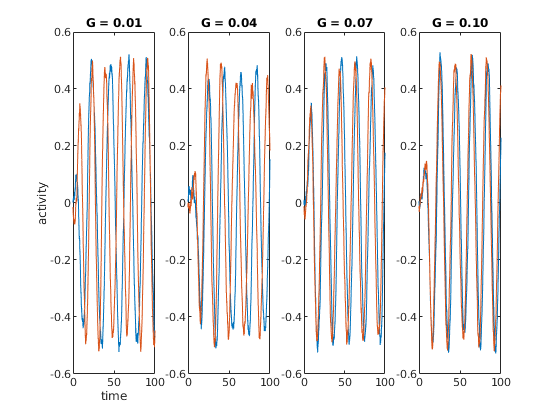

figure
for i=1:4
    for t=2:t_steps
        X(:,t) = X(:,t-1) + dt *...
            ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* X(:,t-1) - omega .* Y(:,t-1) +...
            Gs(i) * sum(C .* (meshgrid(X(:,t-1)) - meshgrid(X(:,t-1))'),2)) + ...
            dsig * randn(2,1);
        Y(:,t) = Y(:,t-1) + dt *...
            ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* Y(:,t-1) + omega .* X(:,t-1) +...
            Gs(i) * sum(C .* (meshgrid(Y(:,t-1)) - meshgrid(Y(:,t-1))'),2)) + ...
            dsig * randn(2,1);
    end
    subplot(1,4,i)
    plot(T,X')
    title(sprintf('G = %.2f', Gs(i)))
end
subplot(1,4,1)
xlabel('time')
ylabel('activity')

C = [0,1;1,0];
Gs = linspace(0.01,0.1,4);

t_start = 0;                      % simulation start time (seconds)
t_end = 100;                      % simulation end time (seconds)
dt = 1e-2;                        % time step (seconds)

t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);

freq = [0.045;0.06];              % intrinsic frequencies (Hz)
omega = 2 * pi * freq;            % angular velocities
alpha = -0.01;
X = randn(2,t_steps) .* 1e-2;
Y = randn(2,t_steps) .* 1e-2;

sigma = 0.02;
dsig = sigma * sqrt(dt);

fprintf('Hopf model - two region - with noise; alpha = -0.01')

Hopf model - two region - with noise; alpha = -0.01

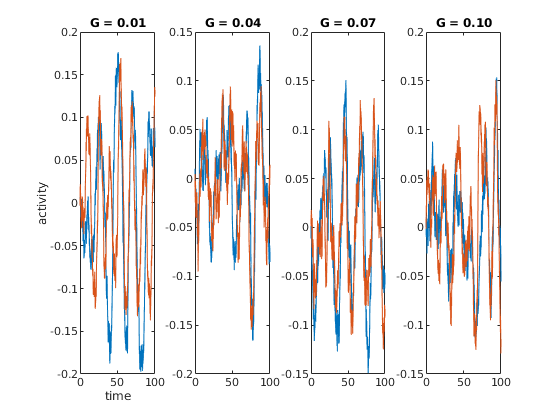

figure
for i=1:4
    for t=2:t_steps
        X(:,t) = X(:,t-1) + dt *...
            ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* X(:,t-1) - omega .* Y(:,t-1) +...
            Gs(i) * sum(C .* (meshgrid(X(:,t-1)) - meshgrid(X(:,t-1))'),2)) + ...
            dsig * randn(2,1);
        Y(:,t) = Y(:,t-1) + dt *...
            ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* Y(:,t-1) + omega .* X(:,t-1) +...
            Gs(i) * sum(C .* (meshgrid(Y(:,t-1)) - meshgrid(Y(:,t-1))'),2)) + ...
            dsig * randn(2,1);
    end
    subplot(1,4,i)
    plot(T,X')
    title(sprintf('G = %.2f', Gs(i)))
end
subplot(1,4,1)
xlabel('time')
ylabel('activity')

### Whole brain

#### **Load and arrange data**

tasks =  {'RS';...
    'MR';...
    'OD';...
    'NUM'};

load('fDATA_7T_3DMC_HP_CSF_WD.mat','TS')
load('sDATA_HCP_Q3_SLT_GS')

n_regions = 82;             % number of ROIs (ignore the last 3 regions)
[n_subjects,...             % retrieve number of subjects,
    n_tasks,...             % number of tasks
    ~,...                   %
    n_time] = size(TS);     % and number of time points from size of TS

TS = permute(TS(:,:,1:n_regions,:),[4,3,2,1]); % re-arrange dimensions of data

C = CON(1:n_regions,1:n_regions); % structural connectivity

#### **Bandpass-filtering**

s_rate = 1.5;               % sampling rate (seconds)
s_freq = 1 / s_rate;        % sampling frequency (Hz)
n_freq = 0.5 * s_freq;      % nyquist frequency
c_high = 0.04;              % high-pass cutoff
c_low = 0.07;               % low-pass cutoff
band = [c_high,c_low] / n_freq;

[b,a] = butter(2,band,'bandpass');

TS_filt = zeros(n_time,...  % pre-allocate memory for filtered data
    n_regions,...
    n_tasks,...
    n_subjects);

for s=1:n_subjects
    for t=1:n_tasks
        TS_filt(:,:,t,s) = filtfilt(b,a,TS(:,:,t,s));
    end
end

#### Region-specific intrinsic frequencies

Each region has its own characteristic frequency in the range from $0\ldotp 04\mathrm{Hz}$ to $0\ldotp 07\mathrm{Hz}$  given by the averaged peak frequency of the empirical BOLD signals in that range. This intrinsic frequency is state specific.

n_halftime = n_time / 2;
frequencies = linspace(0,n_freq,n_halftime)';

freq = zeros(n_regions,4);

for t=1:n_tasks
    c = 1;
    for s=1:n_subjects
        ts = TS_filt(:,:,t,s);
        if ~isnan(ts(1,1))  % some data may be missing
            ts_fft = fft(ts);
            amplitude = abs(ts_fft(1:n_halftime,:));
            [~,idx] = max(amplitude);
            % compute mean using Welford's Online algorithm
            freq(:,t) = freq(:,t) + (frequencies(idx) - freq(:,t)) / c;
            c = c + 1;
        end
    end
end

#### Simulation

G = 0.12;
t_start = 0;                      % simulation start time (seconds)
t_end = 950;                      % simulation end time (seconds)
dt = 1e-1;                        % time step (seconds)

t_steps = (t_end - t_start) / dt + 1;
T = linspace(t_start,t_end,t_steps);
omega = 2 * pi * freq(:,1);       % angular velocities (rest)
alpha = -0.056;
X = randn(n_regions,t_steps) .* 0;
Y = randn(n_regions,t_steps) .* 0;

sigma = 0.02;
dsig = sigma * sqrt(dt);

fprintf('Hopf model with 82 regions; G = 0.12; alpha = -0.056')

Hopf model with 82 regions; G = 0.12; alpha = -0.056

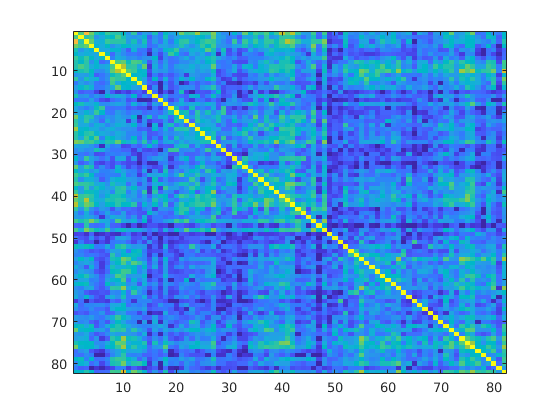

figure
for t=2:t_steps
    X(:,t) = X(:,t-1) + dt *...
        ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* X(:,t-1) - omega .* Y(:,t-1) +...
        G * sum(C .* (meshgrid(X(:,t-1)) - meshgrid(X(:,t-1))'),2)) + ...
        dsig * randn(n_regions,1);
    Y(:,t) = Y(:,t-1) + dt *...
        ((alpha - X(:,t-1).^2 - Y(:,t-1).^2) .* Y(:,t-1) + omega .* X(:,t-1) +...
        G * sum(C .* (meshgrid(Y(:,t-1)) - meshgrid(Y(:,t-1))'),2)) + ...
        dsig * randn(n_regions,1);
end
BOLD = X(:,502:15:end)';
FC = corrcoef(BOLD);

imagesc(FC,[0,0.5])

#### Simulation using the hopf_model class

help hopf_model

  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  %%%                               LICENSE                             %%% 
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  
  Copyright 2019 Mario Senden
  
  This program is free software: you can redistribute it and/or modify
  it under the terms of the GNU Lesser General Public License as published 
  by the Free Software Foundation, either version 3 of the License, or
  (at your option) any later version.
  
  This program is distributed in the hope that it will be useful,
  but WITHOUT ANY WARRANTY; without even the implied warranty of
  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
  GNU Lesser General Public License for more details.
  
  You should have received a copy of the GNU Lesser General Public License
  along with this program.  If not, see <http://www.gnu.org/licenses/>.
  
  
  %%%%%%%%%%%%%%%

Z = hopf_model('connectivity', C,...% structural connectivity
    'omega', 2 * pi * freq(:,1),... % angular velocities (rest)
    'alpha', -0.056,...             % bifurcation parameter
    'g_coupling', 0.12,...          % global coupling
    'sigma', 0.02,...               % noise scaling
    'dt', 1e-1);                    % time step (seconds)

relax_time = 50;                    % relaxation time (seconds)
sim_time = 900 * n_subjects;        % simulation end time (seconds)
sampling_rate = 1.5;                % fMRI sampling rate (seconds)

Z.relax(relax_time);                % let system evolve (relax) for a while
BOLD_sim = Z.simulate(sim_time,...  % perform actual simulation
    sampling_rate);

ans = 0.1200

FC_sim = corrcoef(BOLD_sim);        % compute simulated FC

fprintf('Hopf model with 82 regions; G = 0.12; alpha = -0.056')

Hopf model with 82 regions; G = 0.12; alpha = -0.056

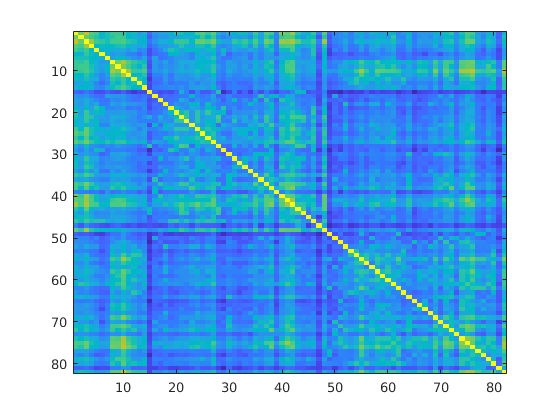

figure
imagesc(FC_sim,[0,0.5])